#  Activity Map_events_arena_binary 

Elapsed time is 0.358395 seconds.
Elapsed time is 0.460431 seconds.


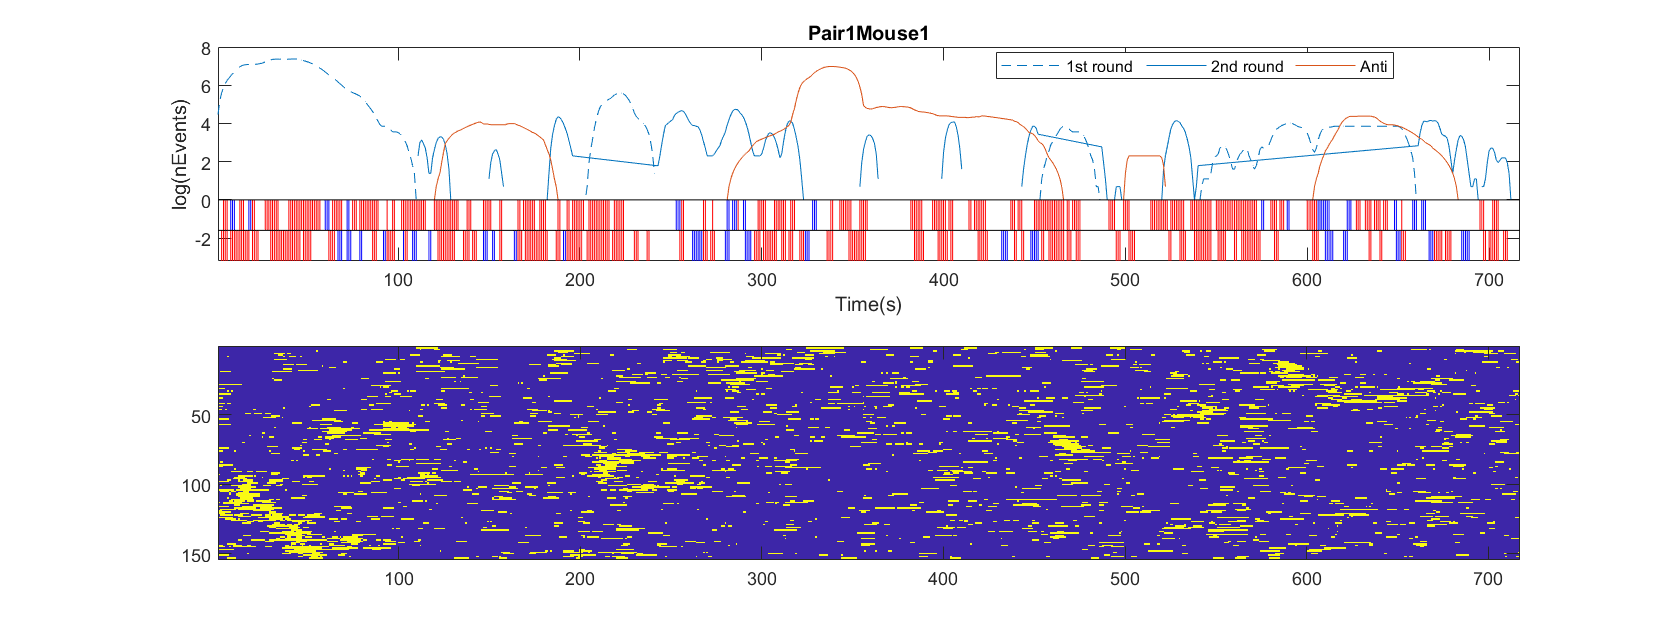

Elapsed time is 0.347249 seconds.
Elapsed time is 0.453596 seconds.


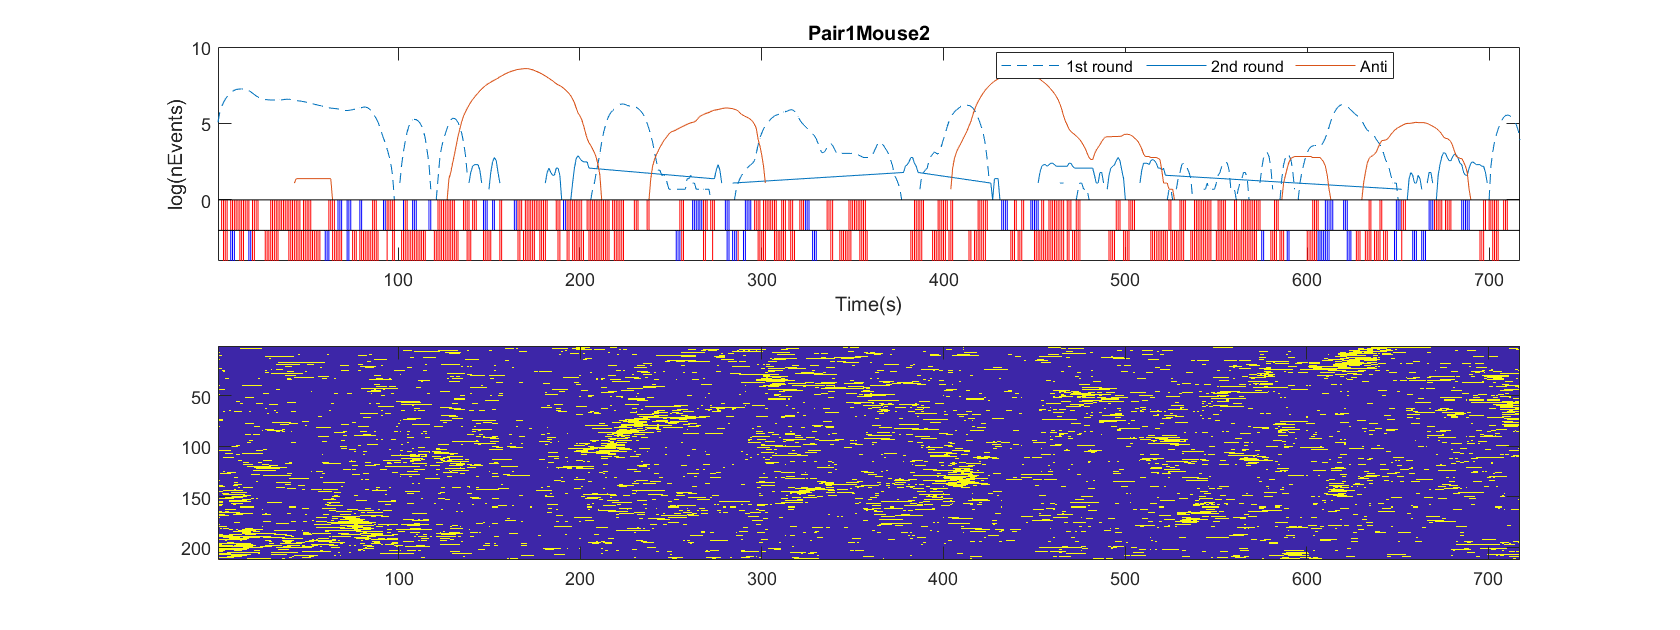

Elapsed time is 0.380243 seconds.
Elapsed time is 0.469370 seconds.


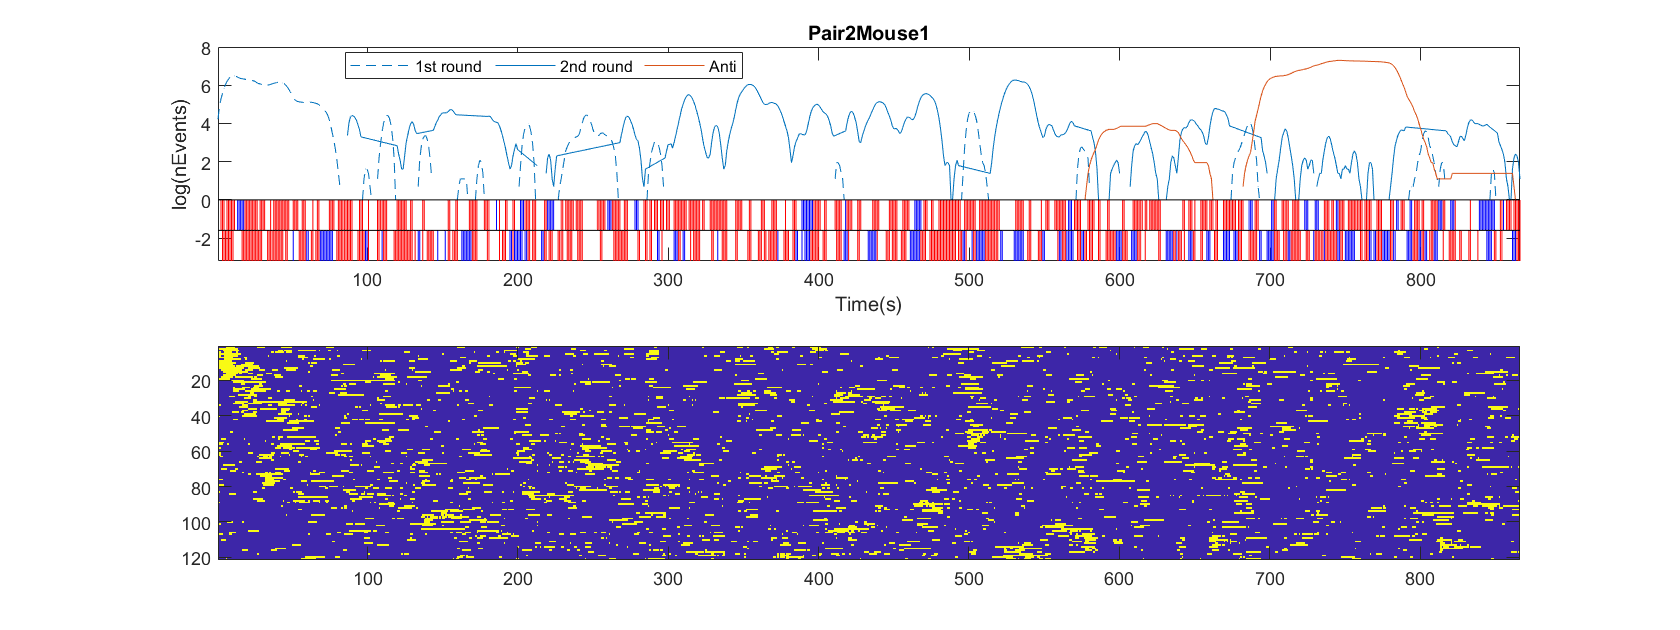

Elapsed time is 0.414350 seconds.
Elapsed time is 0.526084 seconds.


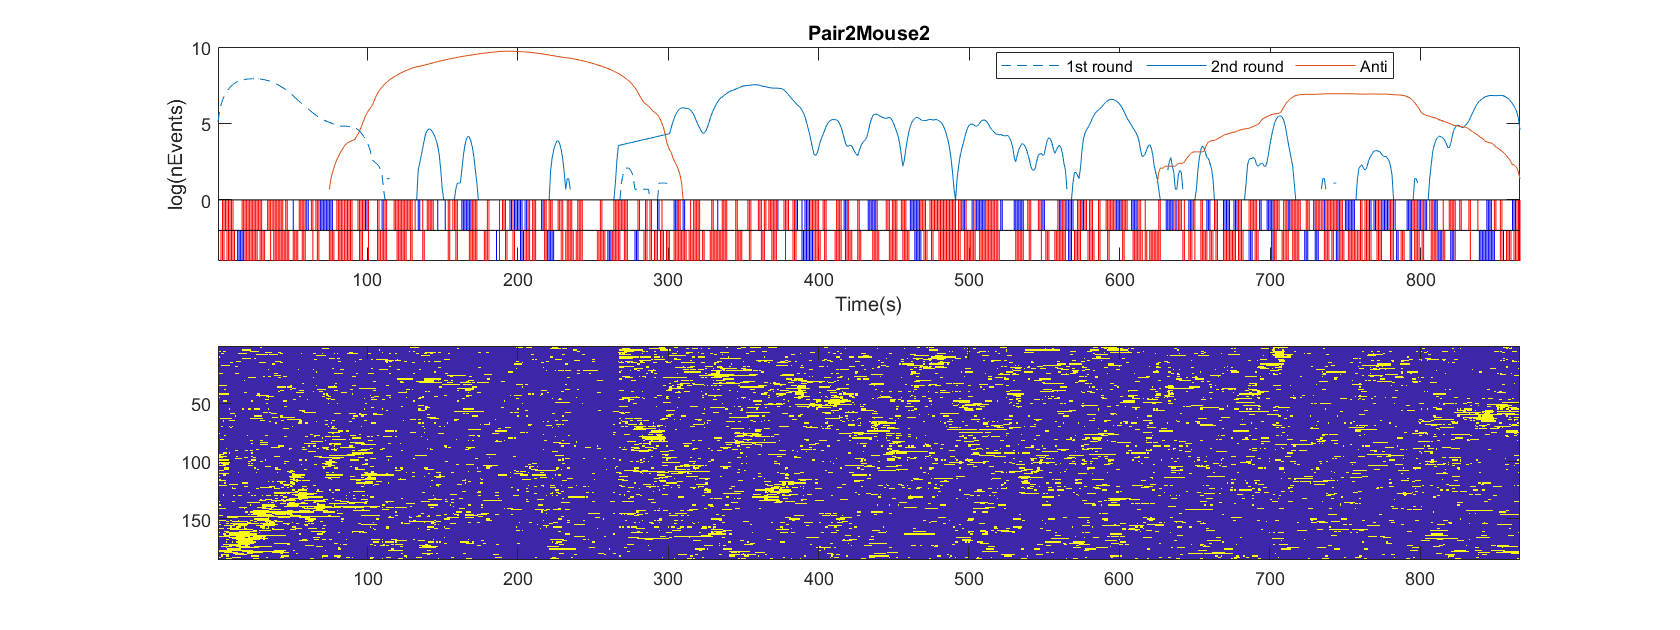

Elapsed time is 0.345899 seconds.
Elapsed time is 0.430881 seconds.


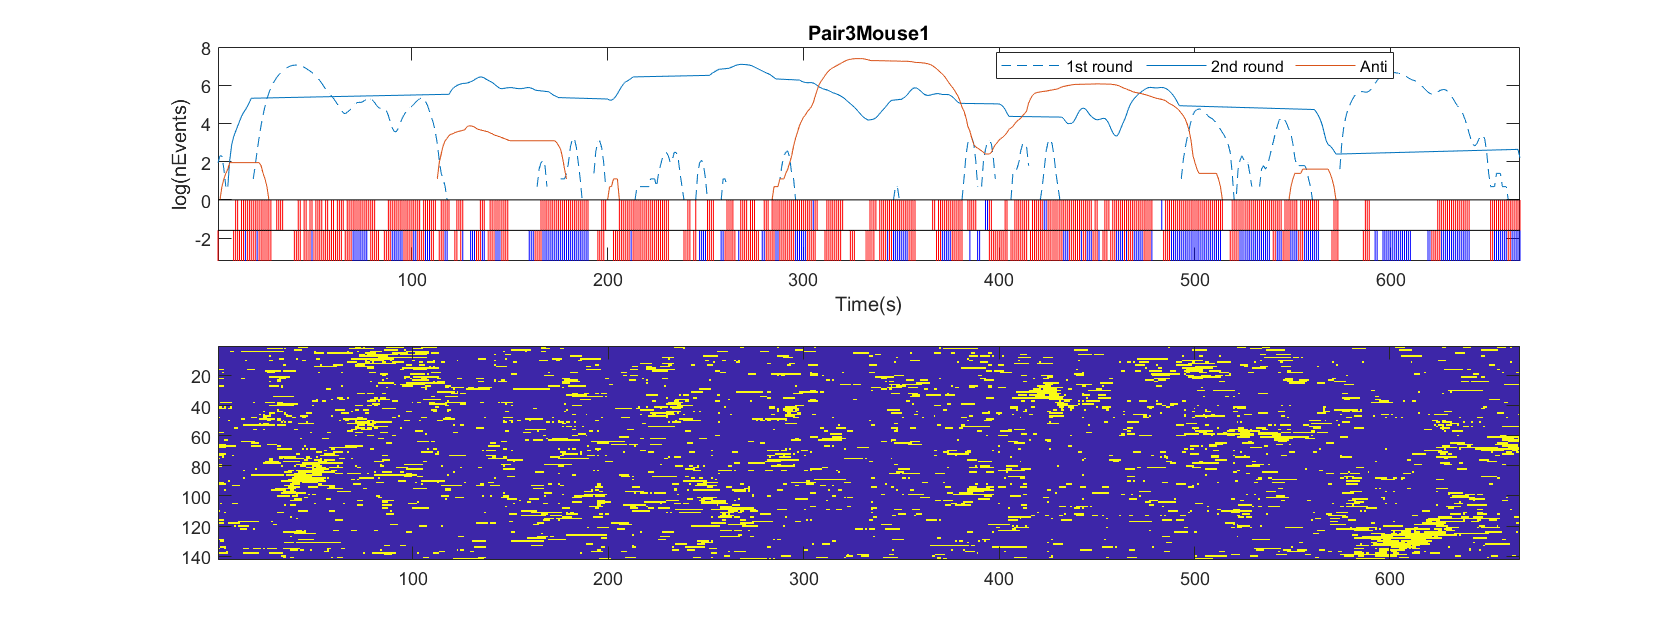

Elapsed time is 0.341112 seconds.
Elapsed time is 0.443985 seconds.


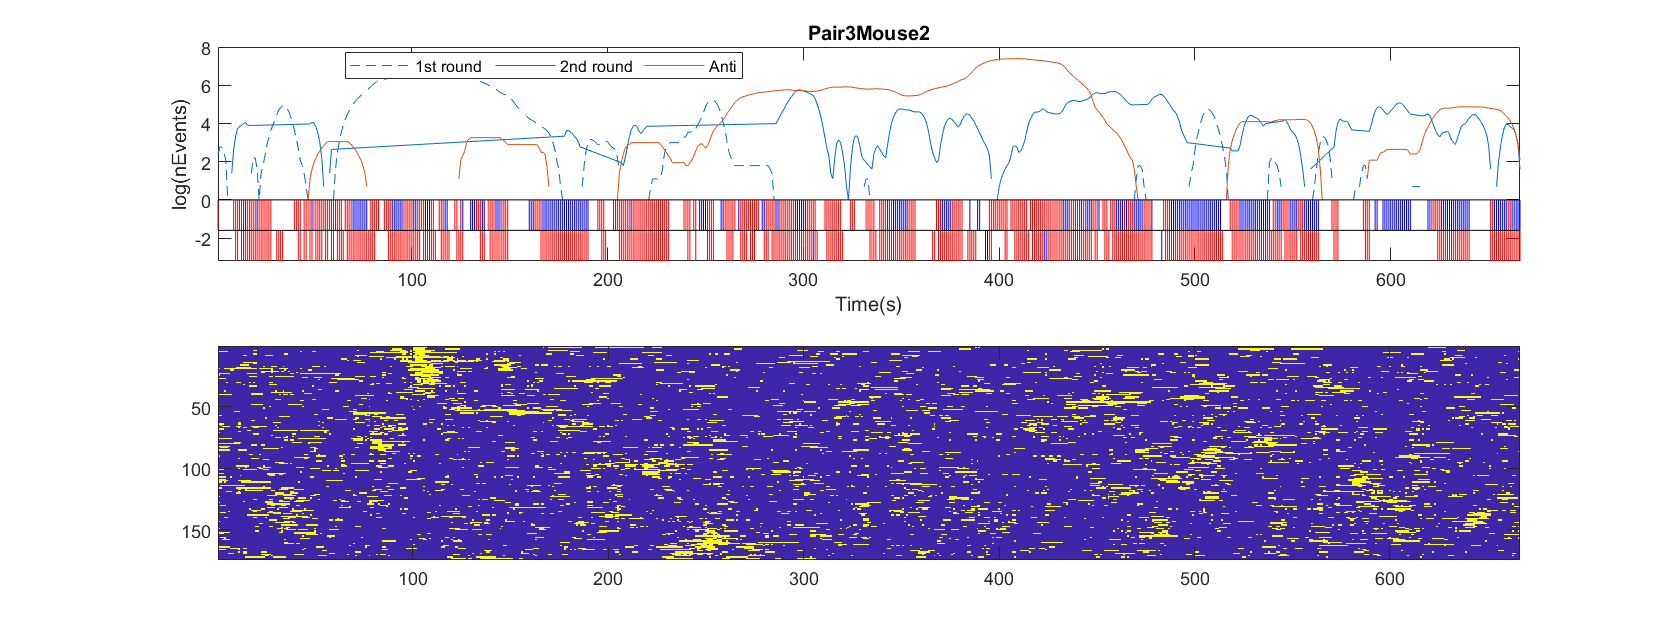

Elapsed time is 0.335188 seconds.
Elapsed time is 0.433925 seconds.


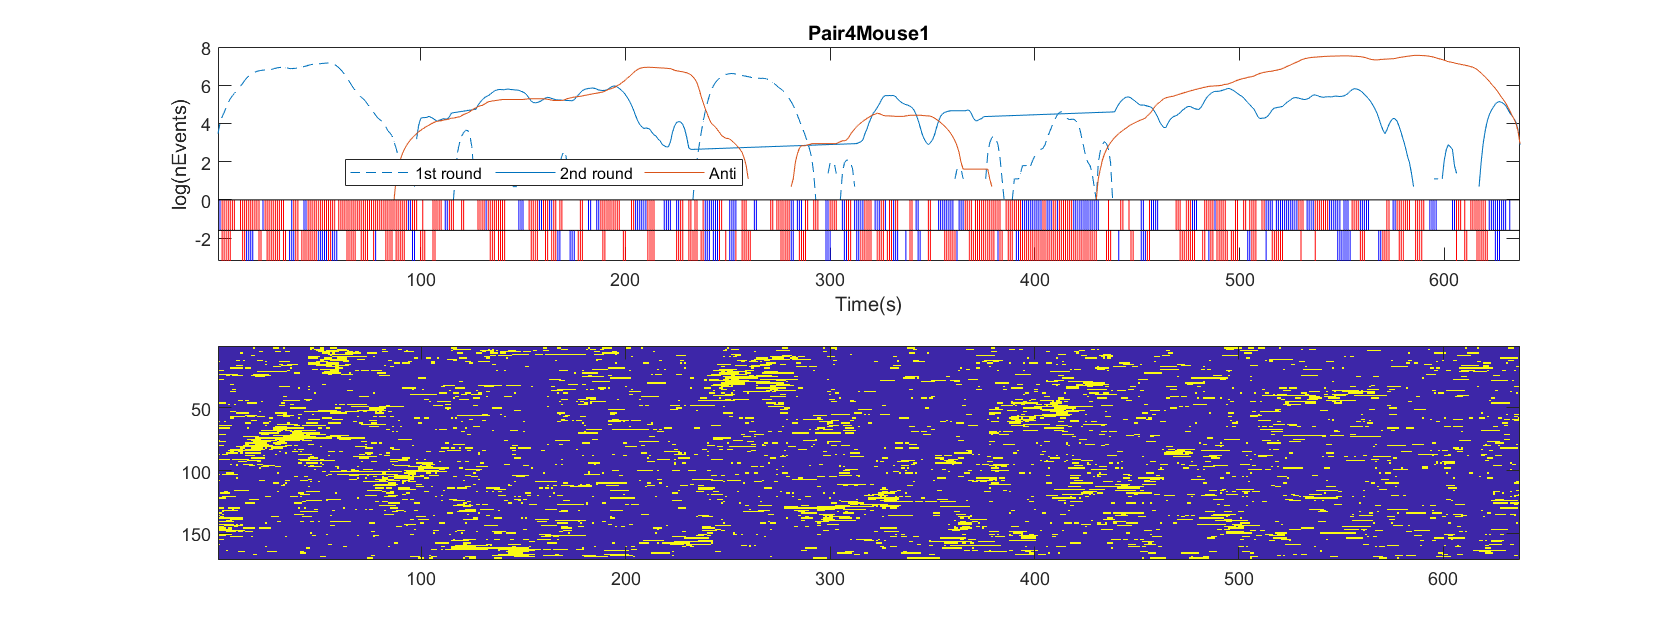

Elapsed time is 0.333885 seconds.
Elapsed time is 0.424610 seconds.


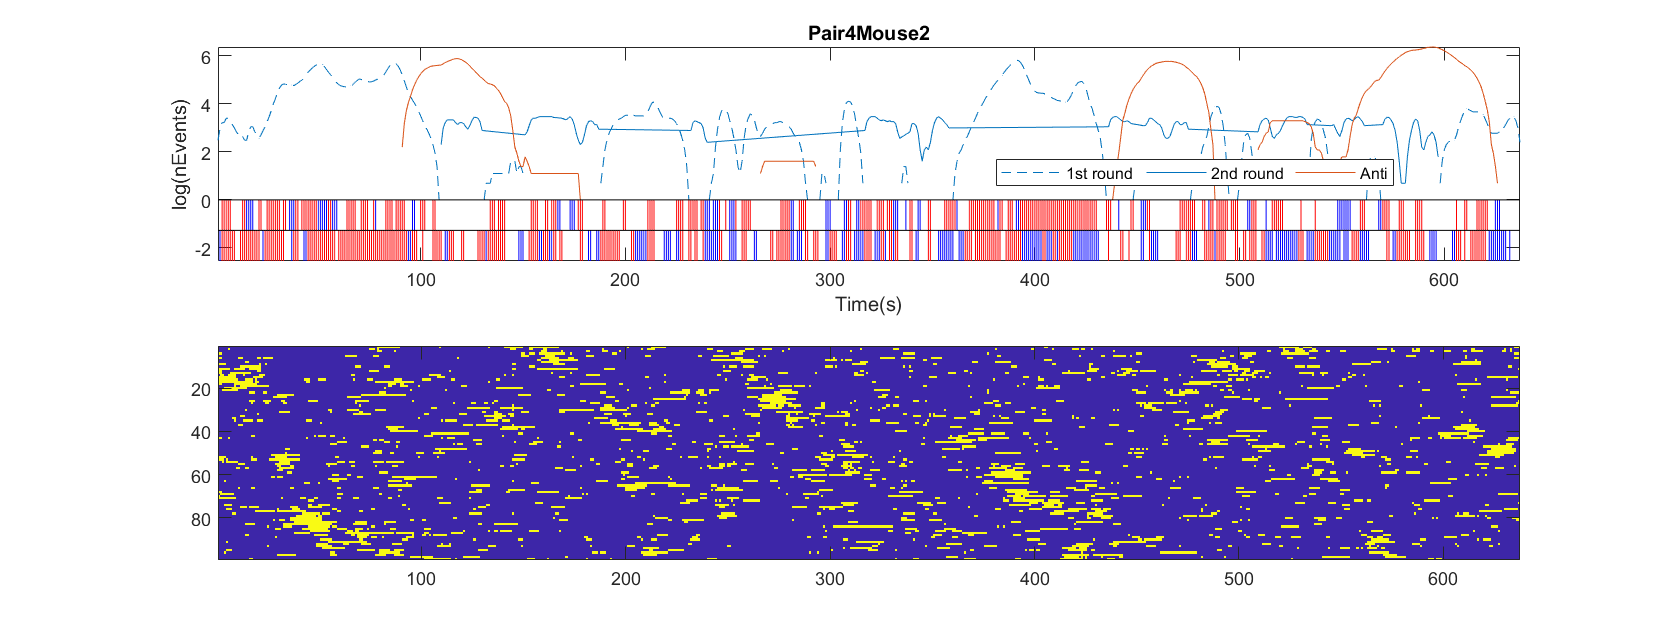

Elapsed time is 0.332000 seconds.
Elapsed time is 0.425008 seconds.


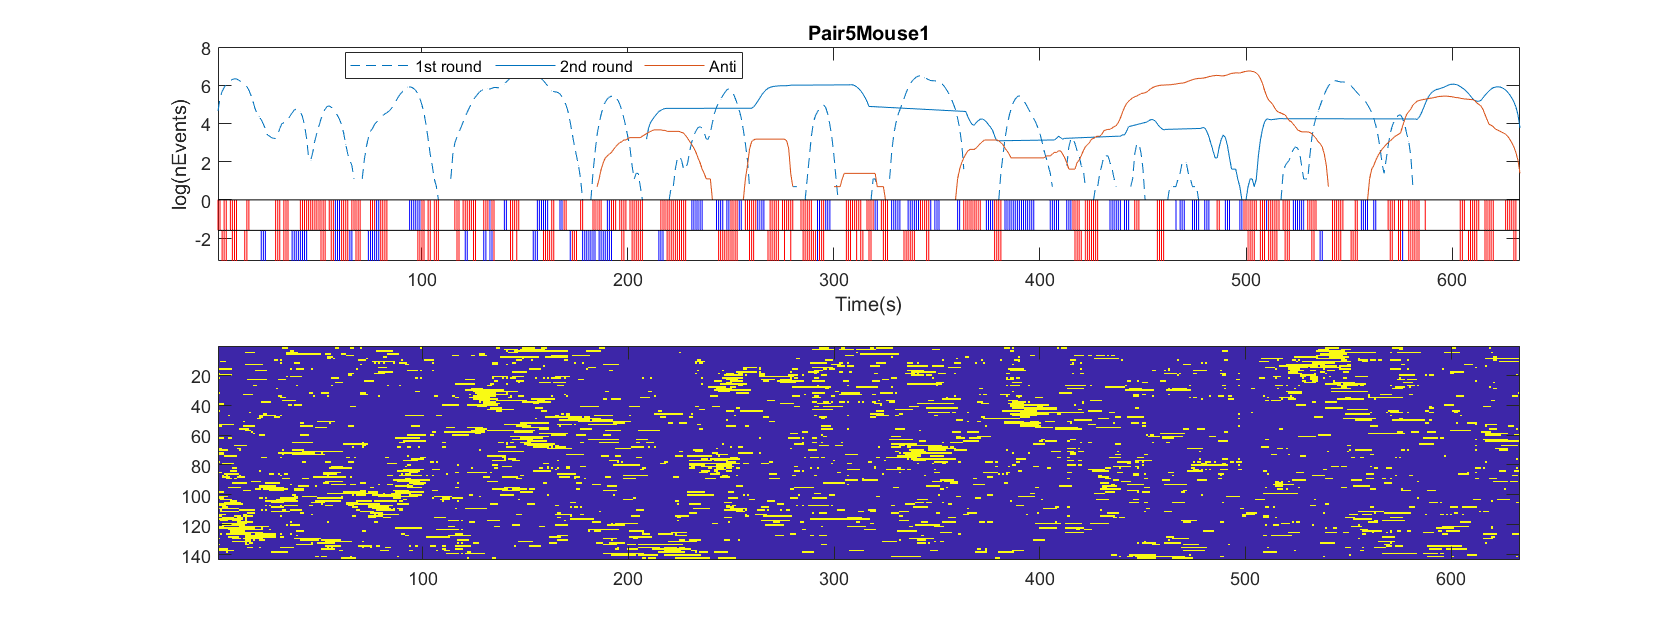

Elapsed time is 0.343594 seconds.
Elapsed time is 0.427737 seconds.


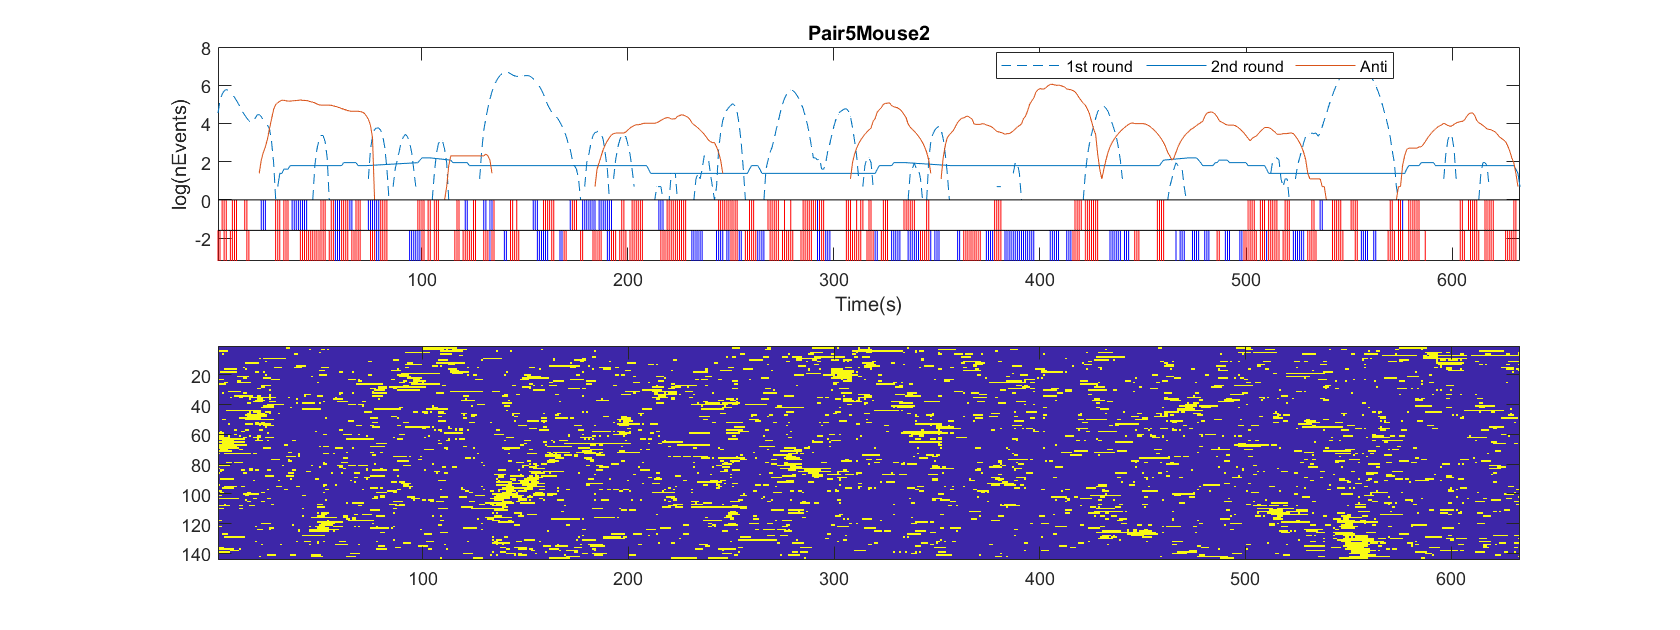

Elapsed time is 0.380572 seconds.
Elapsed time is 0.461966 seconds.


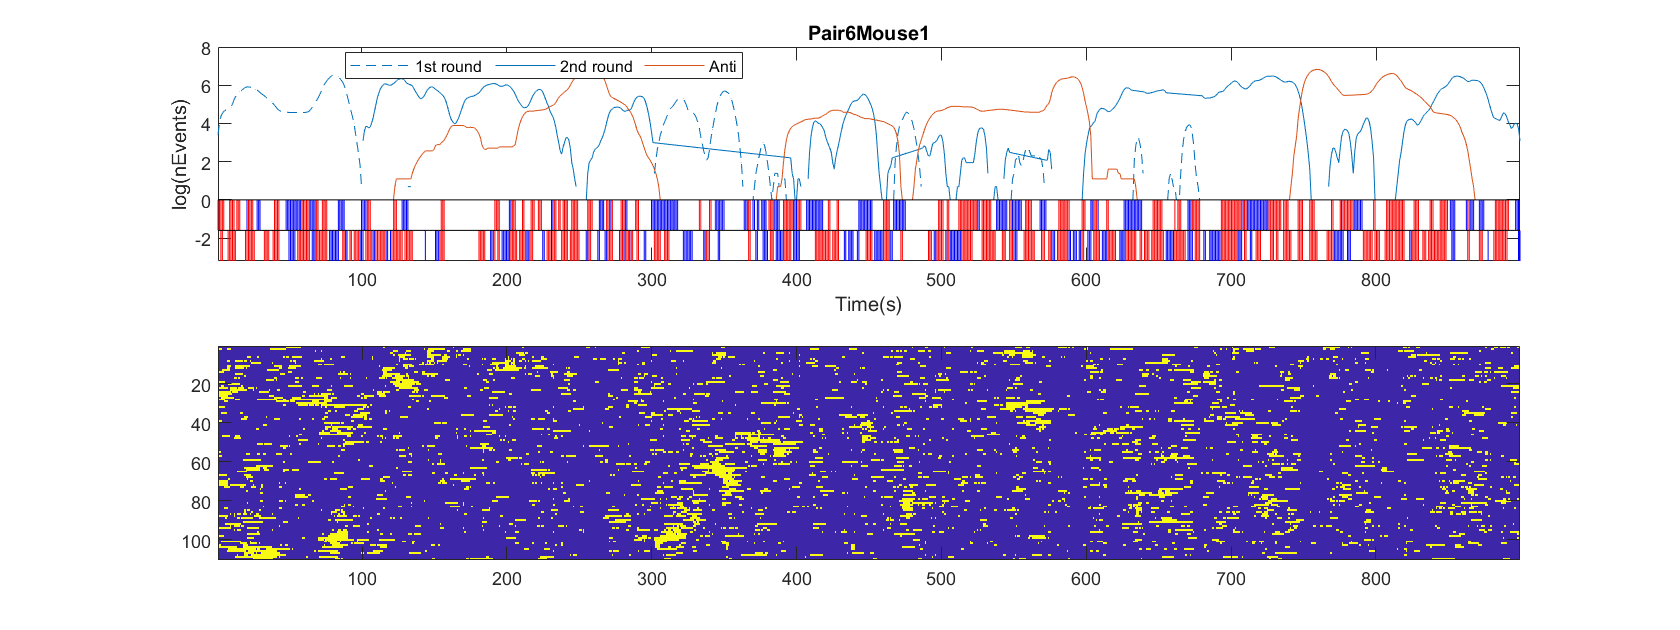

Elapsed time is 0.384507 seconds.
Elapsed time is 0.468191 seconds.


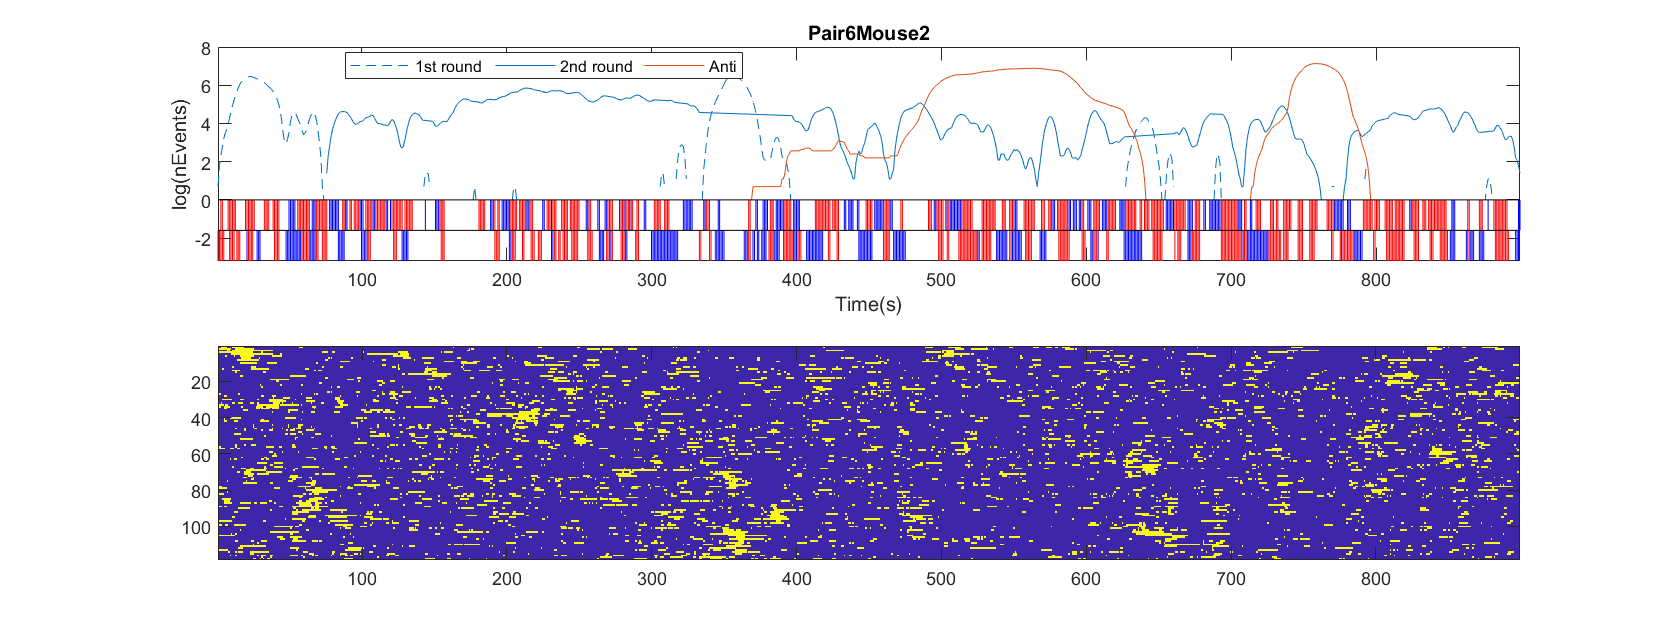

Elapsed time is 0.374729 seconds.
Elapsed time is 0.481253 seconds.


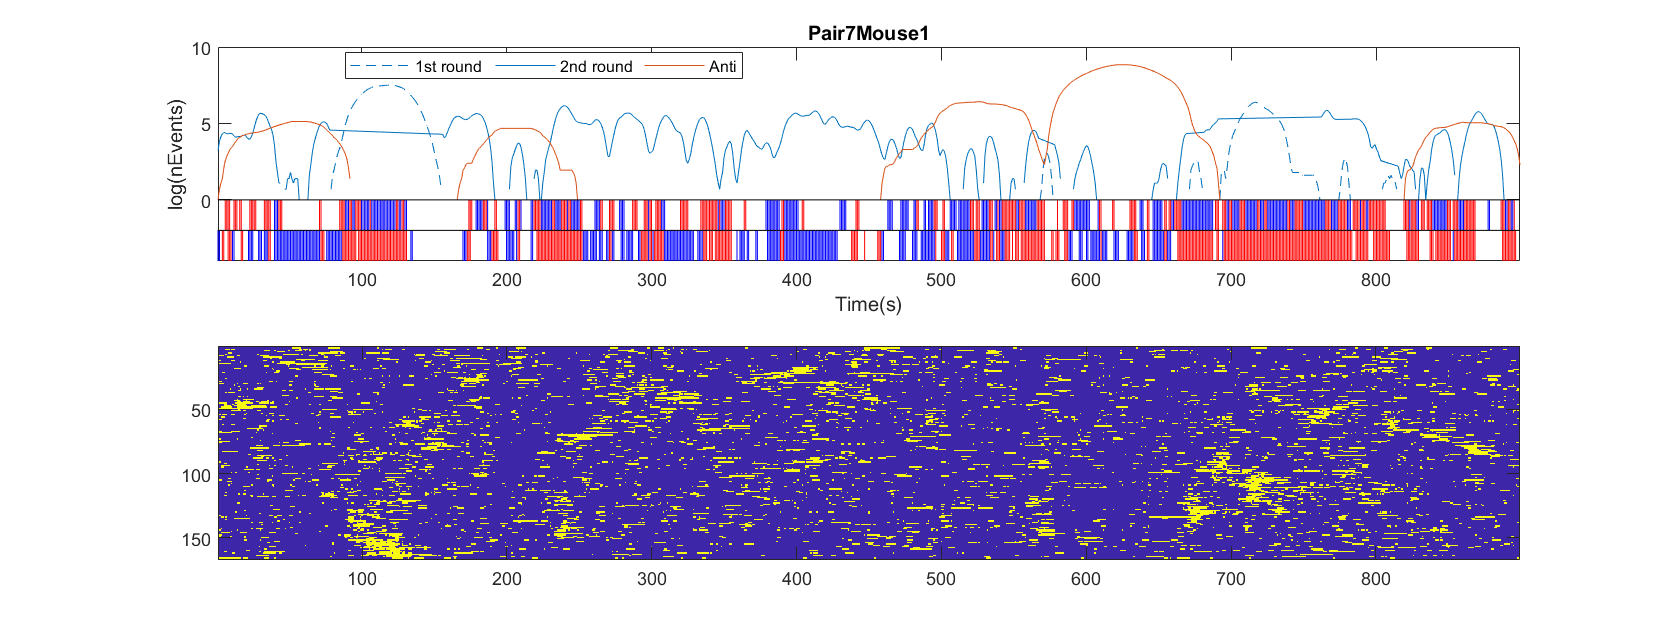

Elapsed time is 0.378504 seconds.
Elapsed time is 0.451038 seconds.


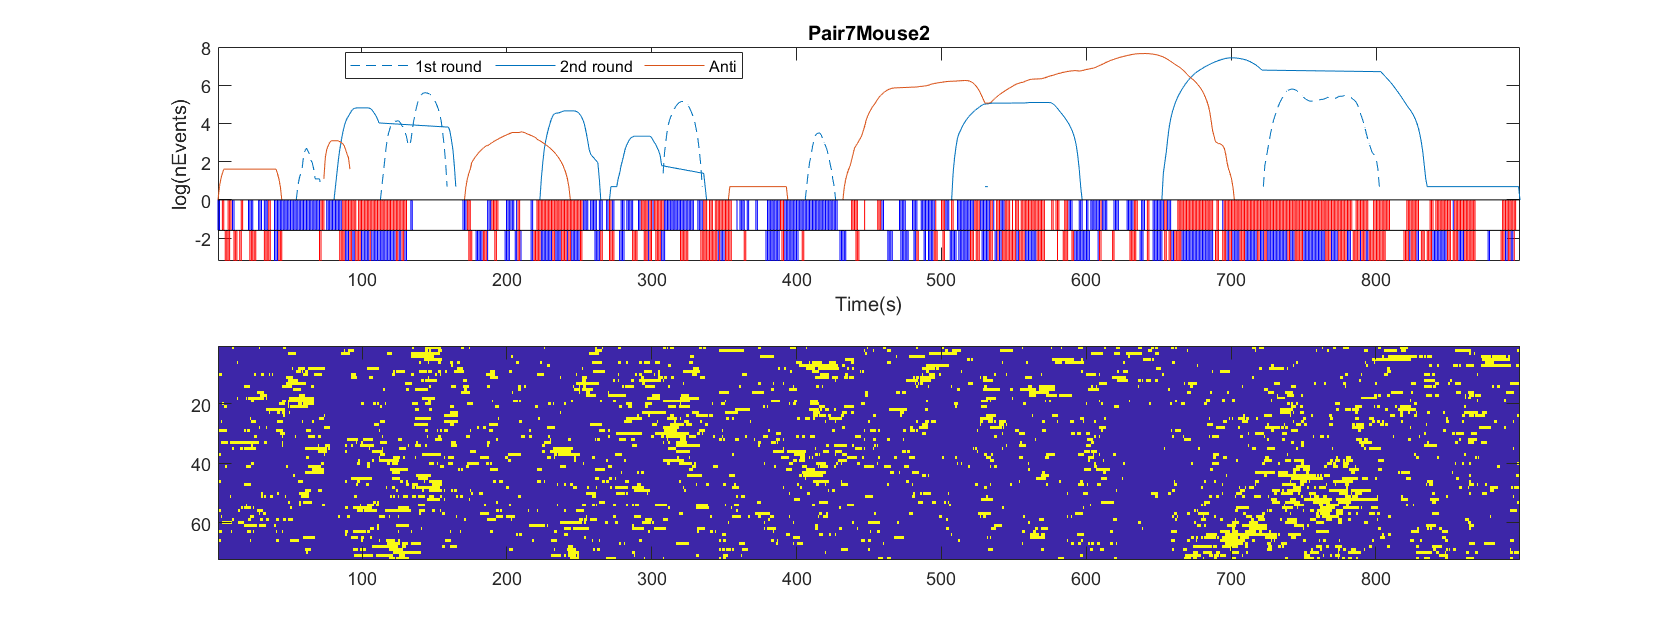

Elapsed time is 0.344182 seconds.
Elapsed time is 0.452934 seconds.


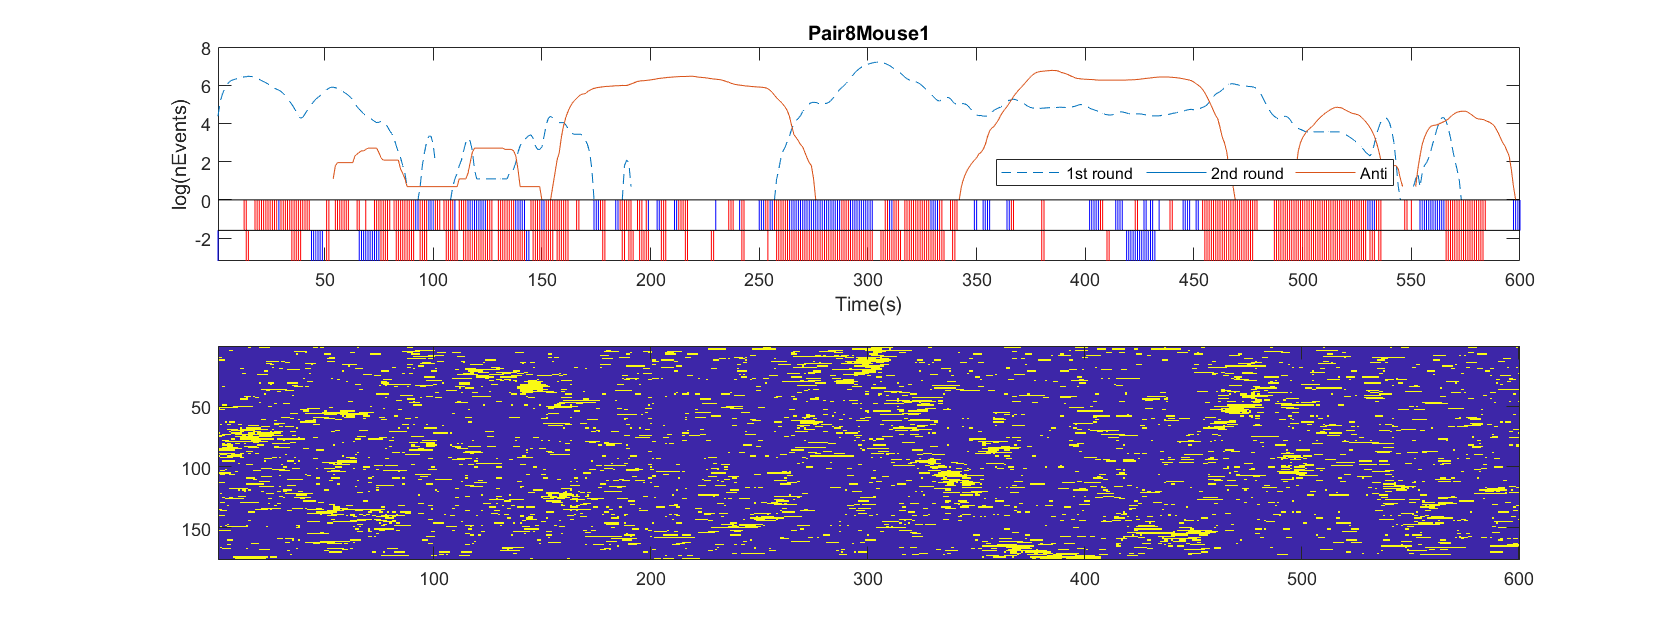

Elapsed time is 0.332249 seconds.
Elapsed time is 0.410322 seconds.


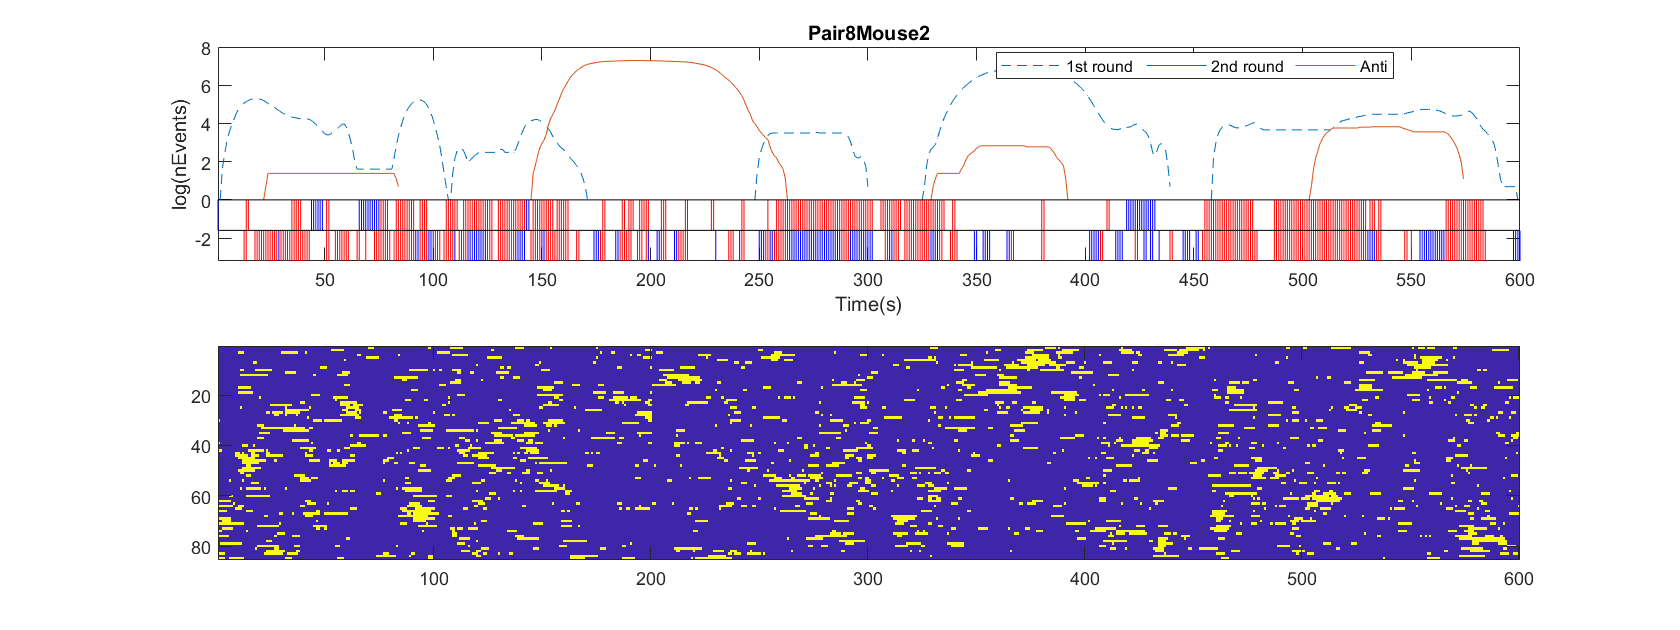

Elapsed time is 0.359248 seconds.
Elapsed time is 0.447194 seconds.


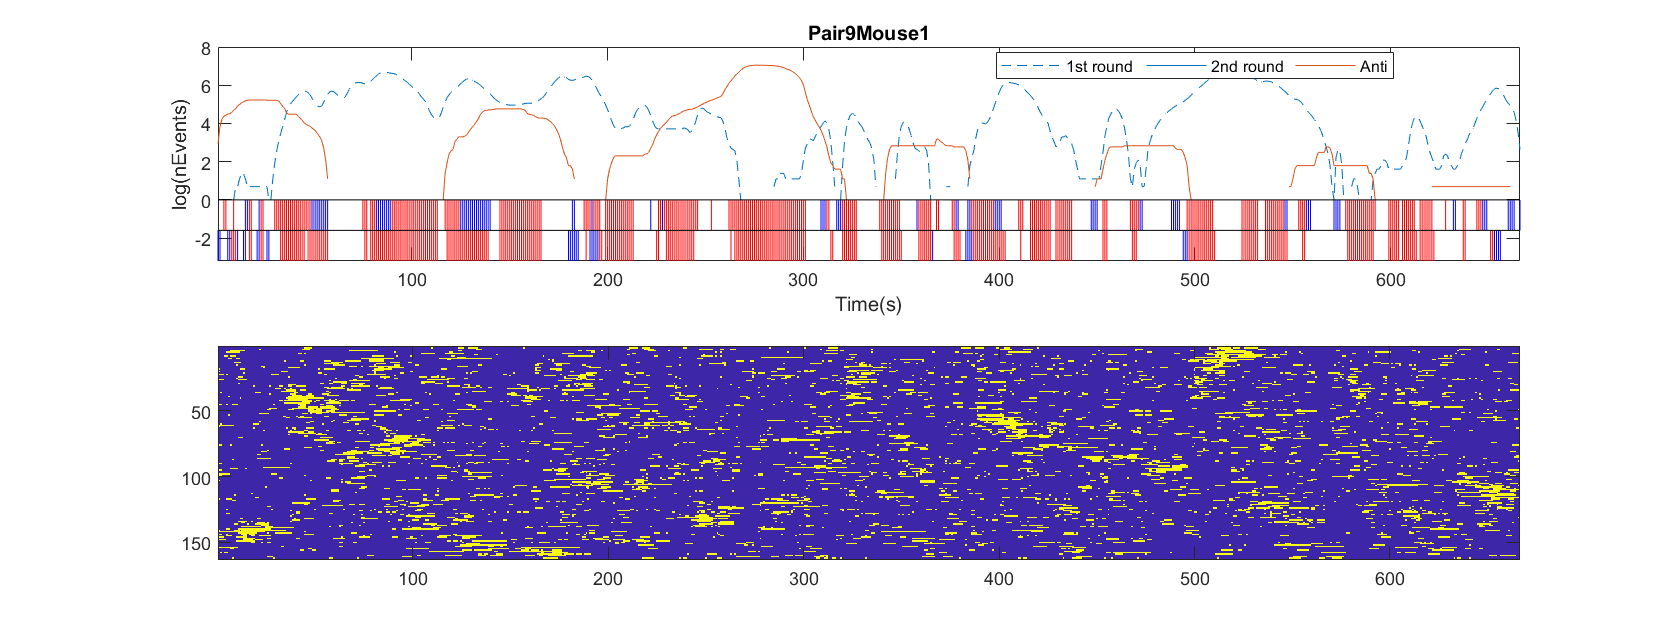

Elapsed time is 0.358260 seconds.
Elapsed time is 0.430689 seconds.


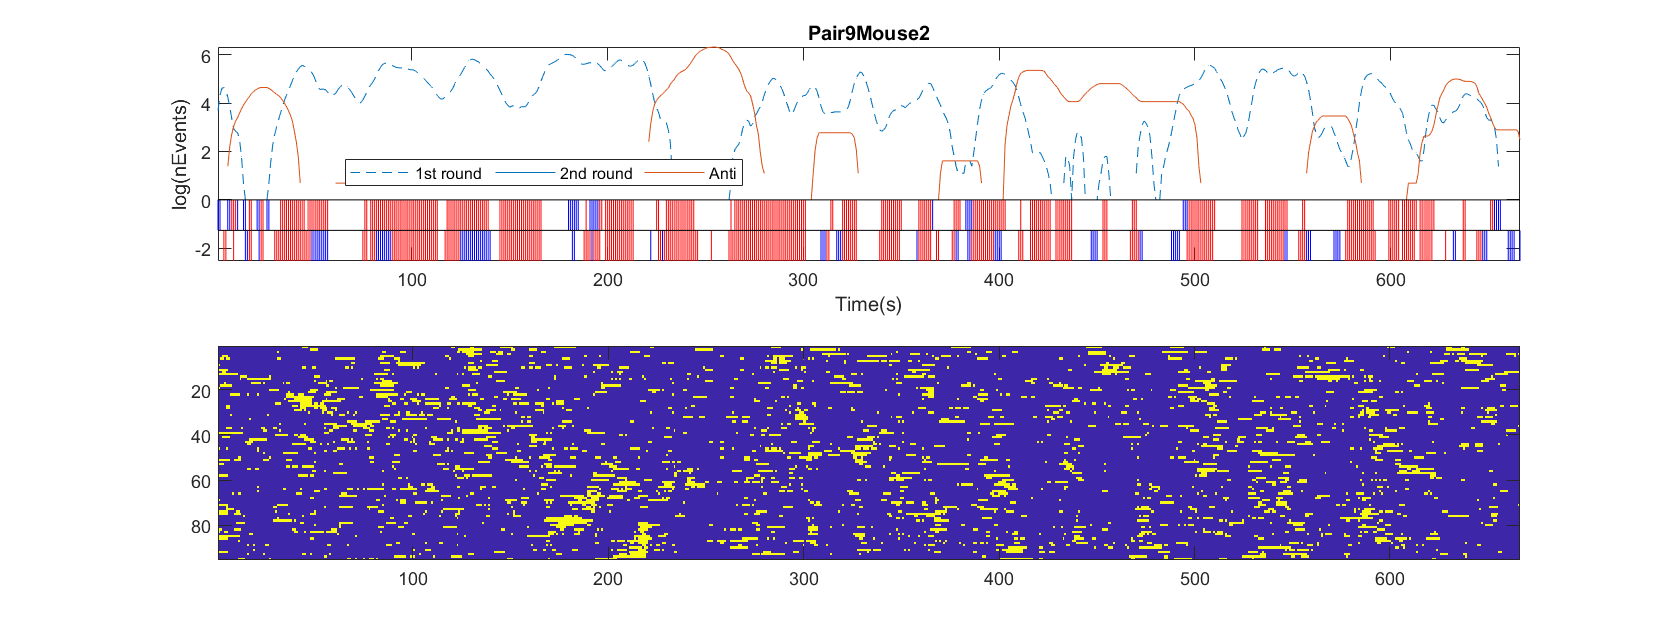

Elapsed time is 0.496609 seconds.
Elapsed time is 0.598452 seconds.


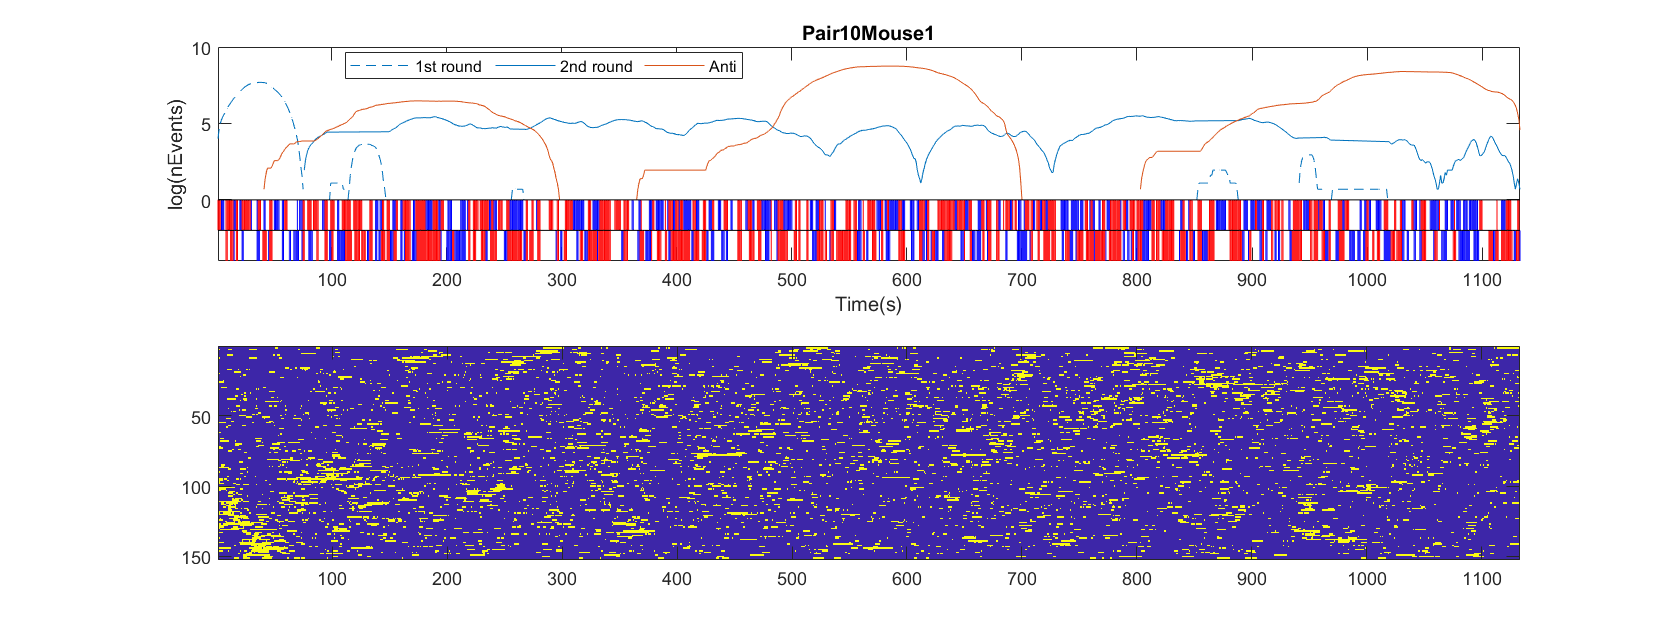

Elapsed time is 0.499351 seconds.
Elapsed time is 0.586683 seconds.


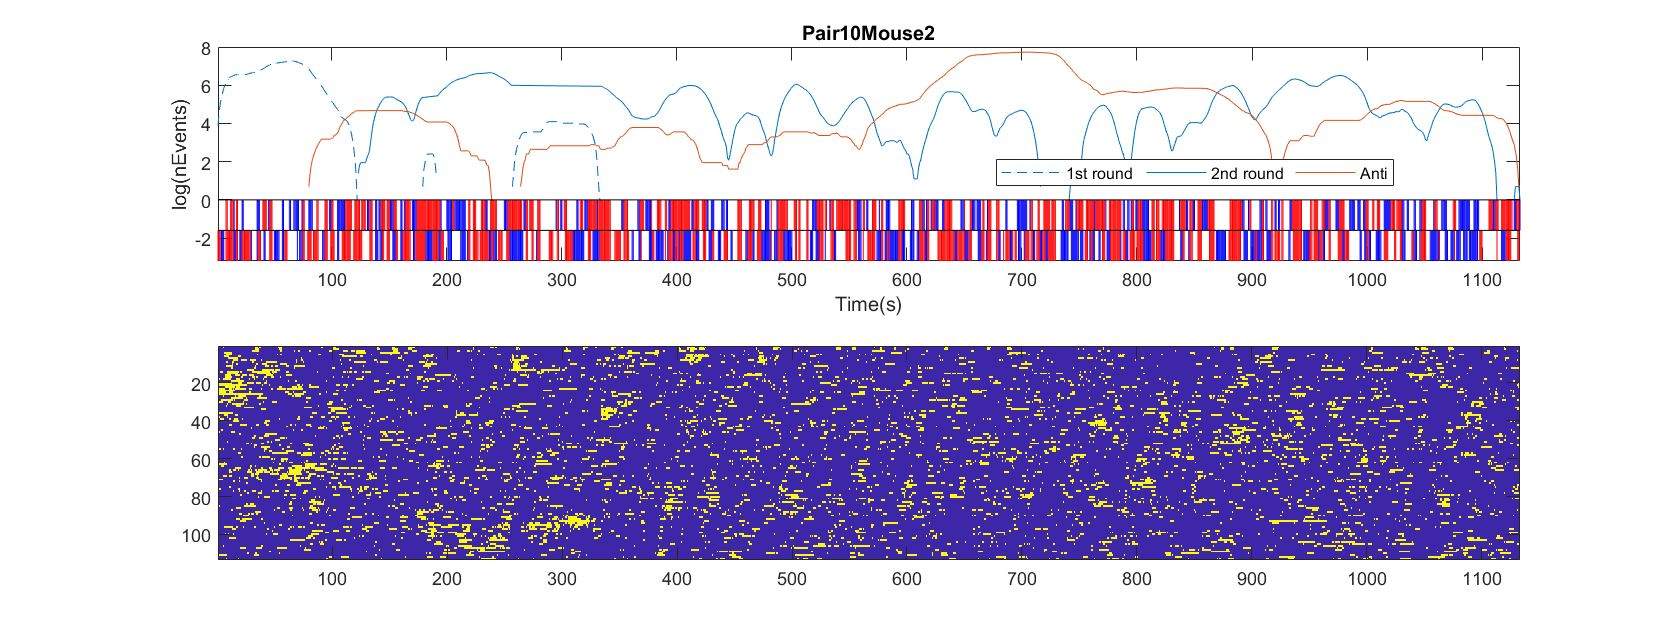

load('em_arena_antievent_binary_0.05.mat')
load('em_arena_binary_th0.5.mat')
load('HC_SYN_10Psocial_R1_030119_UPD.mat')
close all
ca_cl=em{1,1}.ca_cl;
N=10;
x=0;th=1;
for p=1:N
    for m=1:2
        sbename=E{p}{m}.BehaviorNames;obename=E{p}{setdiff([1 2],m)}.BehaviorNames;
        beh=E{p}{m}.BehaviorVectors; % self behaviour 
        opbeh=E{p}{setdiff([1 2],m)}.BehaviorVectors; % opponent behaviours 
        em1=em{1,1}.ne{p,m}';em2=em{2,1}.ne{p,m}';em2filter=em{2,1}.timefilter{p,m};antieve=anti{1,1}.ne{p,m}';
        x=x+1;f1=figure(x);f1.Position(3)=2*f1.Position(3);
        subplot(2,1,1)
        eventplot_arena(em1,em2,em2filter,antieve,beh,sbename,opbeh,obename,"logscale",true);
        title(sprintf('Pair%dMouse%d',p,m))
        subplot(2,1,2) % raster plot 
        S0=ca_cl{p,m};
        ops.iPC=1:35;
        [isort1, ~, ~] = mapTmap(S0, ops);
        imagesc(S0(isort1,:))
    end 
end